# **Portada**

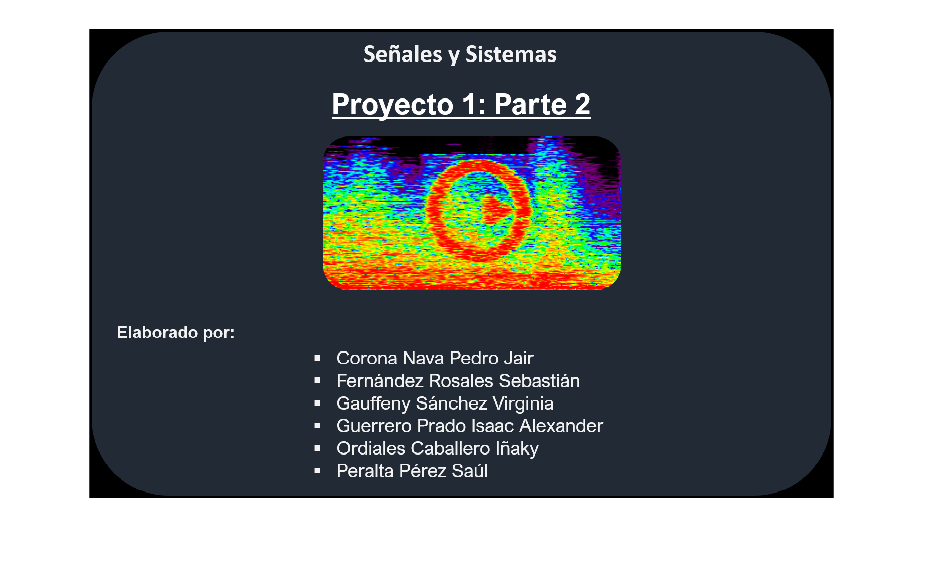

 Cómo desea ingresar su audio?


	1. Seleccionar archivo en la carpeta actual.


	2. Grabar un audio nuevo.




 Seleccione archivo.


 Archivo seleccionado: 'AudioPrueba.mp4'


 Desea escuchar el audio? (1 para sí, 2 para no).


 Oprima una tecla para continuar ...


%% NUEVO
clc;

clear;
imshow("PortadaP2.png");

# **Obtencion del audio**

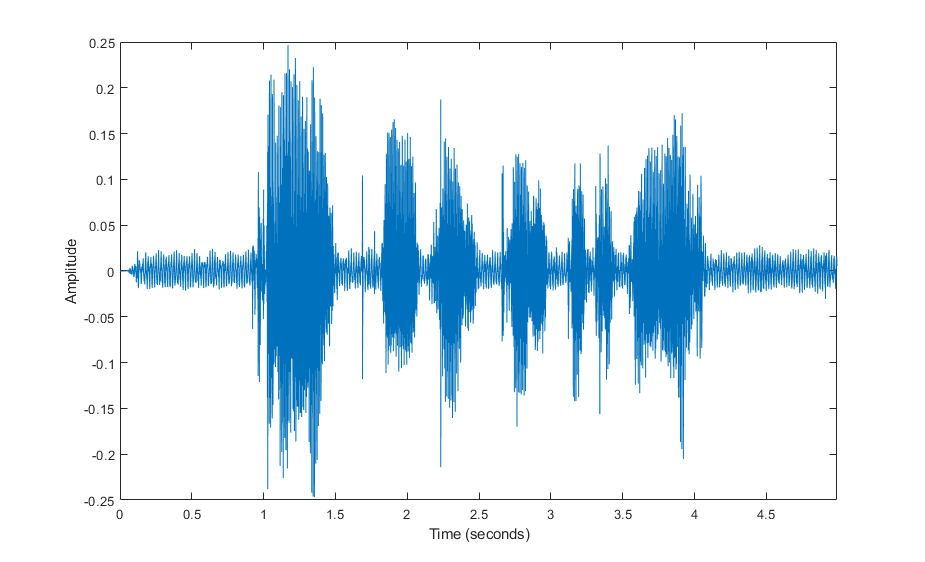

fprintf(" Cómo desea ingresar su audio?\n");
fprintf("\t1. Seleccionar archivo en la carpeta actual.\n");
fprintf("\t2. Grabar un audio nuevo.\n\n");
prompt = ' Opción audio: ';
opcion = input(prompt);

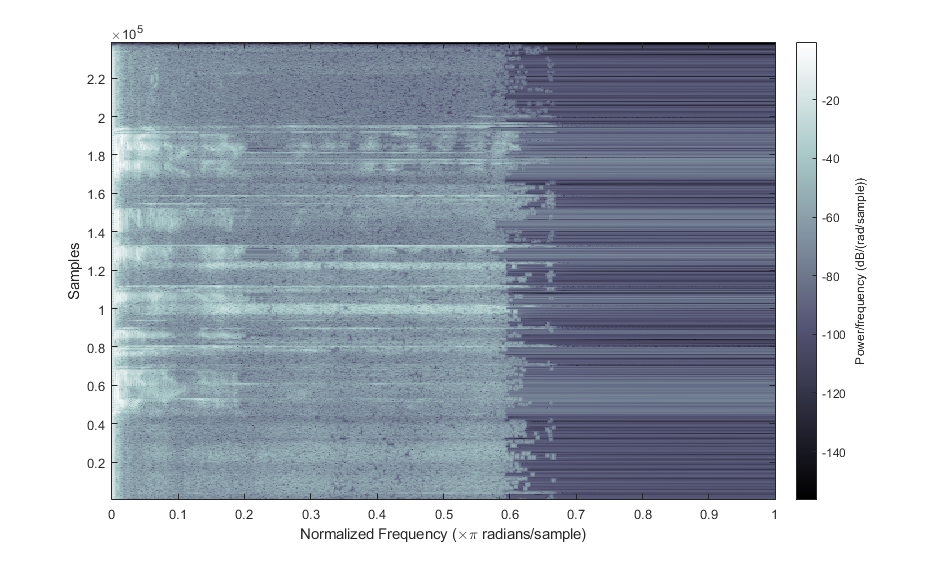


while(opcion~=1 && opcion~=2)
    fprintf(" \n ** La opción no es valida, vuelva a ingresar un valor.\n");
    opcion = input(prompt);
end

if(opcion==1)
    fprintf("\n Seleccione archivo.\n");
    nombre = uigetfile('*.*');
    [s, fs] = audioread(nombre);
    fprintf(" Archivo seleccionado: '%s'\n", nombre);
    fprintf(" Desea escuchar el audio? (1 para sí, 2 para no).");
    prompt = ' Opción escuchar: ';
    opcion = input(prompt);
    while(opcion~=1 && opcion~=2)

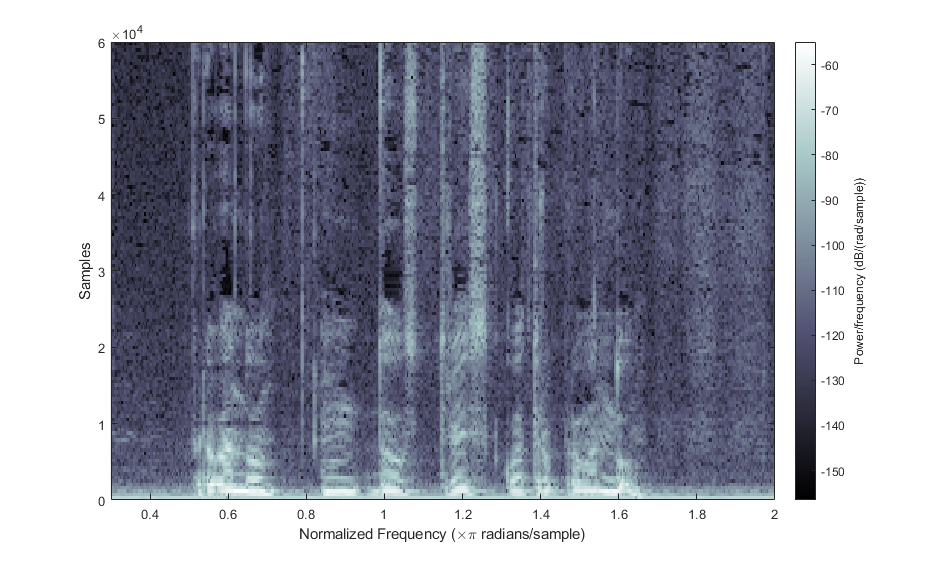

        fprintf(" \n ** La opción no es valida, vuelva a ingresar un valor.\n");
        opcion = input(prompt);
    end
    if(opcion==1)

        fprintf("\n Reproduciendo audio...\n");
        sound(s, fs);
    end
    
else
    recObj = audiorecorder;
    fprintf("\n De cuántos segundos desea la grabación?: ");
    prompt = ' Opción segundos: '
    sec = input(prompt);
    fprintf("\n** Cuando este listo, apriete una tecla para empezar a grabar.\n");
    pause();
    fprintf("\n Comience a hablar.\n");
    fprintf(" -------------------\n");
    fprintf("\n GRABANDO \n");
    recordblocking(recObj, sec);
    fprintf(" -------------------\n");
    fprintf(" La grabación terminó.\n");
    s = getaudiodata(recObj);
    fs = 8000;
    fprintf(" Desea guardar el audio en un archivo? (1 para sí, 2 para no): ");
    prompt = ' Opción guardar: ';
    opcion = input(prompt);
    while(opcion~=1 && opcion~=2)
        fprintf(" \n ** La opción no es valida, vuelva a ingresar un valor.\n");
        opcion = input(prompt);
    end
    if(opcion==1)
        prompt = ' Ingrese el nombre del archivo, sin extensión: ';
        nombre = input(prompt,'s');
        nombre = strcat(nombre, '.wav');
        audiowrite(nombre, s, fs);
        fprintf("\n Audio guardado...\n");
    end
end

fprintf("\n Oprima una tecla para continuar ...\n");
pause();
%% [s fs] = audioread('Nombre del audio'); %% Se quita porque se maneja antes


# **Acondicionamiento**

modi=s(:,1);
t=(0:1/fs:(length(modi)-1)/fs);
plot(t,modi)
xlabel('Time (seconds)')
ylabel('Amplitude')
xlim([0 t(end)])
n = length(modi); 
Npower2 = 2^nextpow2(n);
onda=modi;

for i=1 :(n)
    onda(i)=modi((n-i+1));
    %onda=modi;
end
%onda=-50.*onda;

# **FFT**

y = fft(onda,Npower2)/n;  

# **Espectrograma**


spectrogram(onda,1024,512)
colormap bone 
%spectrogram(y,1024,512),xlim([0.3 2]),ylim([0 0.6e5])
spectrogram(y,512,64)
%colormap bone ,
xlim([0.3 2]),ylim([0 0.6e5])